clear all; close all;

load('Mean_NDVI_for_forest_20y.mat')

filename = 'MYD13Q1.061_250m_aid0001_(2000-2021).nc';
ndvi = ncread(filename, '_250m_16_days_NDVI');

A = ~isnan(ndvi(:,:, 15)); % A is a matrix which has the value 1 for
                           % the area we are interested in
[nr, nc, ~] = size(ndvi);
final_matrix = [];
for t = 1:449
    x = ndvi(:,:, t);
    new_col = x(A(:,:));
    new_col = new_col(:);
    final_matrix = [final_matrix new_col];
end
clear t; clear new_col; clear x;

lats = ncread(filename, 'lat');
lons = ncread(filename, 'lon');
%lons = vertcat(zeros(1,1), lons(1:end,:));

lats_all = [];
lons_all = [];
for col = 1:nc
    for row = 1:nr
        if A(row, col) == 1
            lats_all = [lats_all lats(col)];
            lons_all = [lons_all lons(row)];
        end
    end
end
lats_all = lats_all';
lons_all = lons_all';
clear col; clear row; clear A;    

% fetching the time in one row vector
time = ncread(filename, 'time')';
[~,nt] = size(time);
startdate = datetime(2000,1,1);
dates = startdate + days(time);
years =[];
months = [];
for day = dates
    [y,m,~]=ymd(day);
    years = [years y];
    months = [months m];
end
clear y; clear startdate; clear day; clear m; clear time;
final_matrix=[years; months; final_matrix]; 

final_matrix_summer = [];
for i = 1:nt
    if (5 < months(i)) && (months(i) < 10)
        final_matrix_summer = [final_matrix_summer final_matrix(:, i)];
    end
    
end
clear i;clear final_matrix; clear nt;
[~,nt] = size(final_matrix_summer);

final_years = []; % each column has the maximum value for that year, 
for y = 2002:2021
    ndvi_y = [];
    for t = 1:nt  % nt is number of images
        if final_matrix_summer(1, t) == y
            ndvi_y = [ndvi_y final_matrix_summer(:, t)];
        end
    end
    % now take the average of top 3 maximum for that year
    final_years = [final_years nanmean(maxk(ndvi_y,3, 2),2)];
end
clear y; clear t; clear ndvi_y;
clear years; clear months; %clear dates;
clear i;
final_years = [final_years(1,:); final_years(3:end, :)];

### Converting Matrix to Table and taking the mean of every row

negative_ndvi = final_years(2:end, :) < 0;
f = final_years(2:end, :);
f(negative_ndvi) = nan;

#### Calculating the normalised NDVI

(delta_NDVI)/Forest_NDVI for each year

for i = 1:20
    f(:, i) = f(:, i)/NDVI_for_forest(i);
end
clear i;

T = array2table(f);
for i = 1:20 % because 20 years
    T.Properties.VariableNames{i} = num2str(2001 + i);
end
clear i;  

T.Means = nanmean(T{:,:},2);
T.Median = nanmedian(T{:,:},2);
[n_pixels,~] = size(final_matrix_summer(3:end,:));

maximum = [];
for i = 1:n_pixels
    maximum = [maximum max(T{i,1:20})];
end
maximum = maximum';
T.('maximum') = maximum;
clear i; clear maximum;

T.('Latitude') = lats_all;
T.('Longitudes') = lons_all;
%clear lats_all; clear lons_all;
T = movevars(T, 24, 'Before', 1);
T = movevars(T, 25, 'Before', 2);

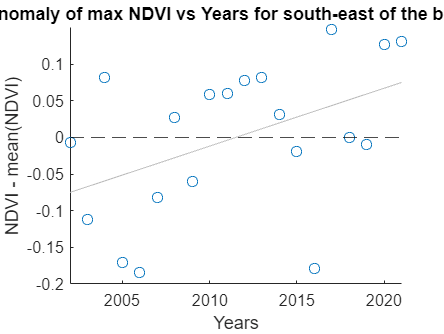

slopes = []; years = 2002:2021;
r_sq = [];
for i = 1:n_pixels
    anomaly = T{i,3:22} - T{i,23};
    A_anomaly = ~isnan(anomaly);
    if length(anomaly(A_anomaly))>1
        scatter(years(A_anomaly), anomaly(A_anomaly))
        xlabel('Years'); ylabel('NDVI - mean(NDVI)'); 
        title(['Anomaly of max NDVI vs Years ' ...
            'for south-east of the bridge']);
        xlim([2002, 2021]); %ylim([-0.25, 0.45]);
        hl = lsline;
        B = [ones(size(hl.XData(:))), hl.XData(:)]\hl.YData(:);
        slopes = [slopes B(2)];
        nan_ind = ~isnan(T{i,3:22});
        [r,~] = corrcoef(years(nan_ind),T{i,3:22}(nan_ind));
        r_sq = [r_sq r(1,2)^2];
    else
        slopes = [slopes NaN];
        r_sq = [r_sq NaN];
    end
end
clear i;
slopes = slopes';
T.('trend_slopes') = slopes;
r_sq = r_sq';
T.('R squared') = r_sq;

yline(0,'k--');

clear hl; clear B; clear slopes; clear r; clear r_sq;
clear A_anomaly; clear anomaly; clear dates; clear years;

slopes = T.('trend_slopes');
A = ~isnan(ndvi(:,:, 15));
Z_slopes = [];
x = 0;
for i = 1:nc
    z_slopes_col = [];
    indx = find(A(:,i)>0);
    start_indx = indx(1);
    end_indx = indx(end);
    z_slopes_col(1:start_indx-1) = NaN;
    z_slopes_col(indx)=slopes(x+1: x+length(indx));
    z_slopes_col(end_indx+1:nr) = missing;
    x = x+length(indx);
    Z_slopes = [Z_slopes z_slopes_col'];
end
clear A; clear end_indx; clear start_indx; clear i; 
clear x; clear z_slopes_col; clear slopes; clear indx

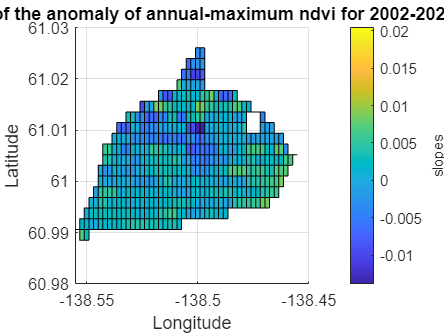

[Y,X]=meshgrid(lats,lons);
s= surf(X,Y,Z_slopes);
view(2);
c = colorbar;
c.Label.String = 'slopes';
xlabel("Longitude"); ylabel("Latitude");
title("Slopes of the anomaly of annual-maximum ndvi for 2002-2021")


clear c; clear s; clear f; clear negative_ndvi



save('Entire_region_Summer_Norm.mat')